# スペクトログラムとDeep CNNによる異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

スペクトログラムとDCNNを活用した異音判定の例題は以下のページをご参照ください。

[https://jp.mathworks.com/help/deeplearning/ug/deep-learning-speech-recognition.html](https://jp.mathworks.com/help/deeplearning/ug/deep-learning-speech-recognition.html)

信号アナライザーによる時間周波数解析は以下のページをご参照ください。

[https://jp.mathworks.com/help/signal/ref/signalanalyzer-app.html](https://jp.mathworks.com/help/signal/ref/signalanalyzer-app.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Deep Learning Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads); %* データのシャッフル
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

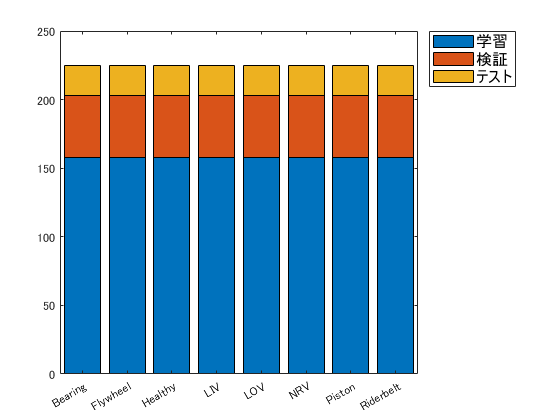

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## データの可視化

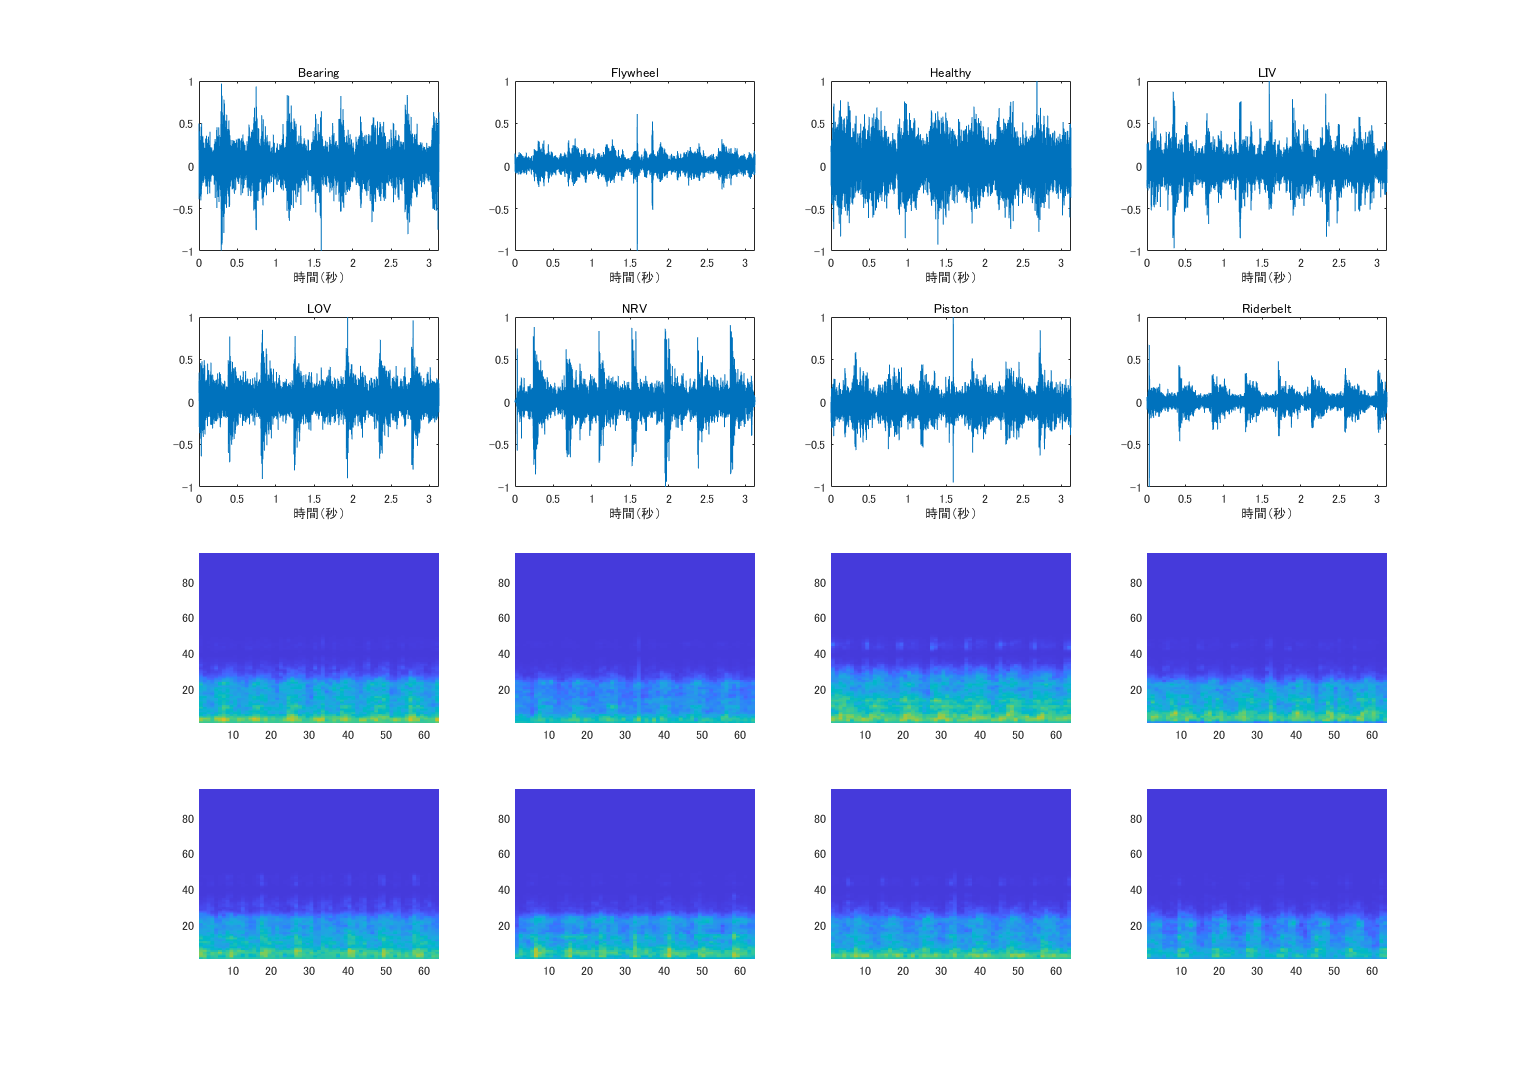

epsil = 1e-6;

% パラメーター
frequencyLimits = [0 1]*pi; % Normalized frequency (rad/sample)
overlapPercent = 50;

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 1]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(4,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
    
    %* 信号アナライザーアプリのMATLABコード生成を活用
    %
    % 対象の信号時間領域へのインデックス
    timeLimits = [1 50000]; % サンプル
    x_ROI = x(:);
    x_ROI = x_ROI(timeLimits(1):timeLimits(2));
    
    % スペクトル推定の計算
    % 以下の関数呼び出しを出力引数なしで実行して結果をプロットします
    [P,F,T] = pspectrum(x_ROI, ...
        'spectrogram', ...
        'FrequencyLimits',frequencyLimits, ...
        'OverlapPercent',overlapPercent);
    
    P = log10(P+epsil);
    spect = imresize(P, [96, 64]);
    XAll(:,:,:,n) = spect;
    
    subplot(4,4,n+8);
    pcolor(spect);
    caxis([-6.5 0]) % カラーマップの範囲の設定
    shading flat
end

## 学習用データの作成

XTrain = zeros(96,64,1,numel(adsTrain.Labels));
YTrain = adsTrain.Labels;

reset(adsTrain)
n = 0;

tic
while hasdata(adsTrain)
    [audioIn,fileInfo] = read(adsTrain);
    
    % 対象の信号時間領域へのインデックス
    timeLimits = [1 50000]; % サンプル
    x_ROI = audioIn(:);
    x_ROI = x_ROI(timeLimits(1):timeLimits(2));
    
    % スペクトル推定の計算
    % 以下の関数呼び出しを出力引数なしで実行して結果をプロットします
    [P,F,T] = pspectrum(x_ROI, ...
        'spectrogram', ...
        'FrequencyLimits',frequencyLimits, ...
        'OverlapPercent',overlapPercent);
    
    P = log10(P+epsil);
    spect = imresize(P, [96, 64]);
    
    n = n+1;
    XTrain(:,:,:,n) = spect;
end
toc

経過時間は 33.670811 秒です。


## 検証用データの作成

XValidation = zeros(96,64,1,numel(adsValidation.Labels));
YValidation = adsValidation.Labels;

reset(adsValidation)
n = 0;

tic
while hasdata(adsValidation)
    [audioIn,fileInfo] = read(adsValidation);
    
    % 対象の信号時間領域へのインデックス
    timeLimits = [1 50000]; % サンプル
    x_ROI = audioIn(:);
    x_ROI = x_ROI(timeLimits(1):timeLimits(2));
    
    % スペクトル推定の計算
    % 以下の関数呼び出しを出力引数なしで実行して結果をプロットします
    [P,F,T] = pspectrum(x_ROI, ...
        'spectrogram', ...
        'FrequencyLimits',frequencyLimits, ...
        'OverlapPercent',overlapPercent);
    
    P = log10(P+epsil);
    spect = imresize(P, [96, 64]);
    
    n = n+1;
    XValidation(:,:,:,n) = spect;
end
toc

経過時間は 10.679113 秒です。


## テスト用データの作成

XTest = zeros(96,64,1,numel(adsTest.Labels));
YTest = adsTest.Labels;

reset(adsTest)
n = 0;

tic
while hasdata(adsTest)
    [audioIn,fileInfo] = read(adsTest);
    
    % 対象の信号時間領域へのインデックス
    timeLimits = [1 50000]; % サンプル
    x_ROI = audioIn(:);
    x_ROI = x_ROI(timeLimits(1):timeLimits(2));
    
    % スペクトル推定の計算
    % 以下の関数呼び出しを出力引数なしで実行して結果をプロットします
    [P,F,T] = pspectrum(x_ROI, ...
        'spectrogram', ...
        'FrequencyLimits',frequencyLimits, ...
        'OverlapPercent',overlapPercent);
    
    P = log10(P+epsil);
    spect = imresize(P, [96, 64]);
    
    n = n+1;
    XTest(:,:,:,n) = spect;
end
toc

経過時間は 5.953313 秒です。


specMin = min(XTrain(:));
specMax = max(XTrain(:));

## データの拡張（水増し）

sz = size(XTrain);
specSize = sz(1:2);
imageSize = [specSize 1];
augmenter = imageDataAugmenter( ...
    'RandXTranslation',[-10 10], ...
    'RandXScale',[0.8 1.2], ...
    'FillValue',log10(epsil));
augimdsTrain = augmentedImageDatastore(imageSize,XTrain,YTrain, ...
    'DataAugmentation',augmenter); % ネットワークへの入力引数

## ネットワークの構築

畳み込み層 x5

classWeights = 1./countcats(YTrain);
classWeights = classWeights'/mean(classWeights);
numClasses = numel(categories(YTrain));

timePoolSize = ceil(imageSize(2)/8);
dropoutProb = 0.2;
numF = 12;
layers = [
    imageInputLayer(imageSize) %* 入力層

    convolution2dLayer(3,numF,'Padding','same')  %*　畳み込み層
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same') %*　プーリング層

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer([1 timePoolSize])

    dropoutLayer(dropoutProb)
    fullyConnectedLayer(numClasses) %* 出力層
    softmaxLayer
    weightedClassificationLayer(classWeights)];

## 学習のオプション

miniBatchSize = 128; % ミニバッチサイズ
validationFrequency = floor(numel(YTrain)/miniBatchSize); % 検証頻度

options = trainingOptions('sgdm', ...
    'InitialLearnRate',10e-4, ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency);

## 学習の開始

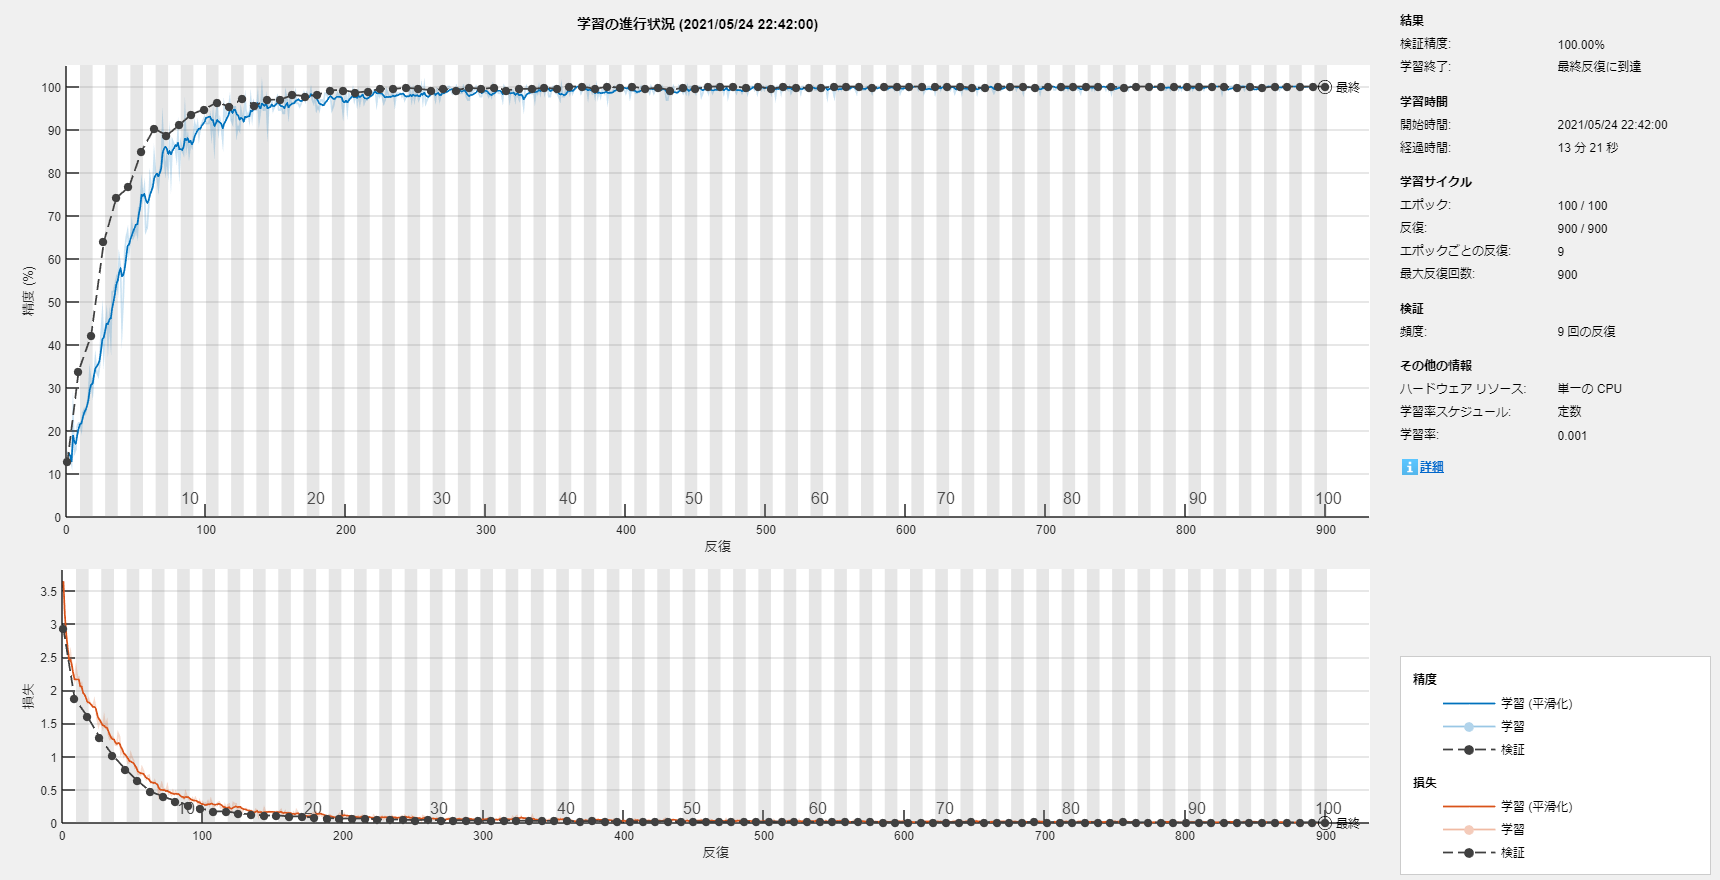

trainedNet = trainNetwork(augimdsTrain,layers,options);

## テスト：精度検証

tblTest

tblTest = 8×2 table
      Label      Count
    _________    _____
    Bearing       22  
    Flywheel      22  
    Healthy       22  
    LIV           22  
    LOV           22  
    NRV           22  
    Piston        22  
    Riderbelt     22  

YPred = classify(trainedNet,XTest);
accuracy = 100*sum(YPred == YTest) / numel(YTest) % 精度（%）

accuracy = 99.4318

## 混同行列

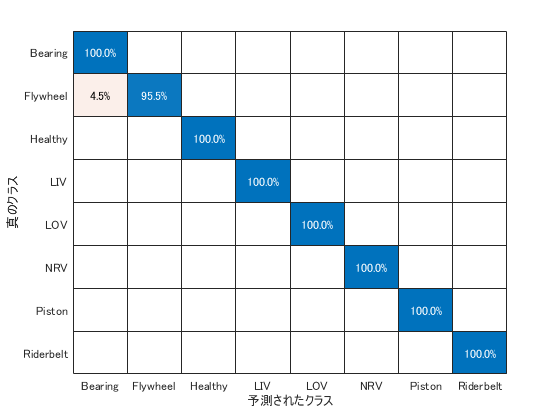

figure; clf;
confusionchart(YTest, YPred,"Normalization","row-normalized")

## 精度の可視化

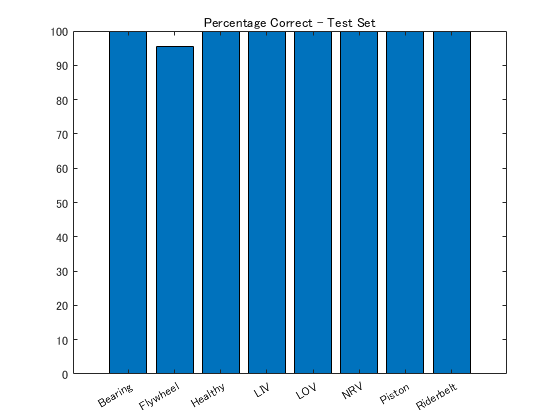

cm = confusionmat(YTest, YPred);
acc = diag(cm)./tblTest.Count*100;
figure; clf;
bar(acc)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

*Copyright 2021 The MathWorks, Inc.*